clear;

% Load dataset
datasetName = "dataset15";
files = metadata.selectPreset(metadata.collect('DataSet/Faulty bearing'), datasetName);

sigTable = preprocess.buildSignalTable(files, 1, 50, @io.readCurrent, @io.readVibro);


pipeline_opt.exclude = [];
[X, Y, featureTbl, featureNames] = features.pipeline(files, pipeline_opt);

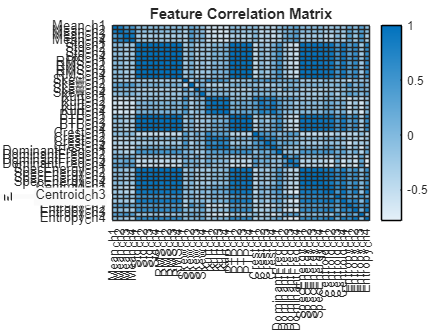

% Features Correlation Check
featureCorrMatrix = corr(X);

figure;
heatmap(featureNames, ...
    featureNames, featureCorrMatrix);
title('Feature Correlation Matrix');

% Output PDF file
outputPDF = 'all_features.pdf';

% Delete existing file if already there
if isfile(outputPDF)
    delete(outputPDF);
end

for i = 1:numel(featureNames)
    fname = featureNames{i};

    figScatter = viz.featureScatter(featureTbl, Y, fname);
    exportgraphics(figScatter, outputPDF, 'Append', true);
    close(figScatter);

    % --- Boxplot ---
    figBox = viz.featureBoxplot(featureTbl, Y, fname);
    exportgraphics(figBox, outputPDF, 'Append', true);
    close(figBox);

    % --- PDF plot ---
    figPDF = viz.featurePDF(featureTbl, Y, fname);
    exportgraphics(figPDF, outputPDF, 'Append', true);
    close(figPDF);
end

disp(['All plots saved to: ', outputPDF]);

All plots saved to: all_features.pdf
